%open folder with the images of the sample
SporesImagesPath=fullfile('D:\Spores\New Pictures\X100\T1');
Images=imageDatastore(SporesImagesPath,'FileExtensions','.tif');

ratio = 0.0515

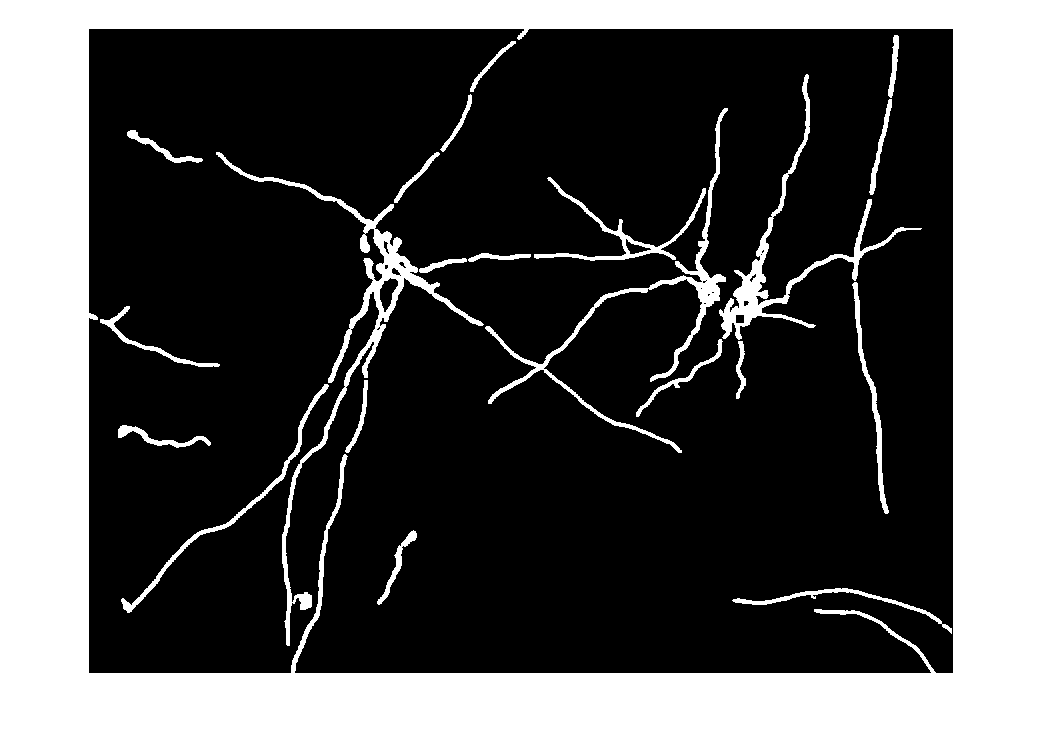

NumGerminatedSpores = 19

AverageLength = 794.0211

ratio = 25.4543

ratio = 0.0393

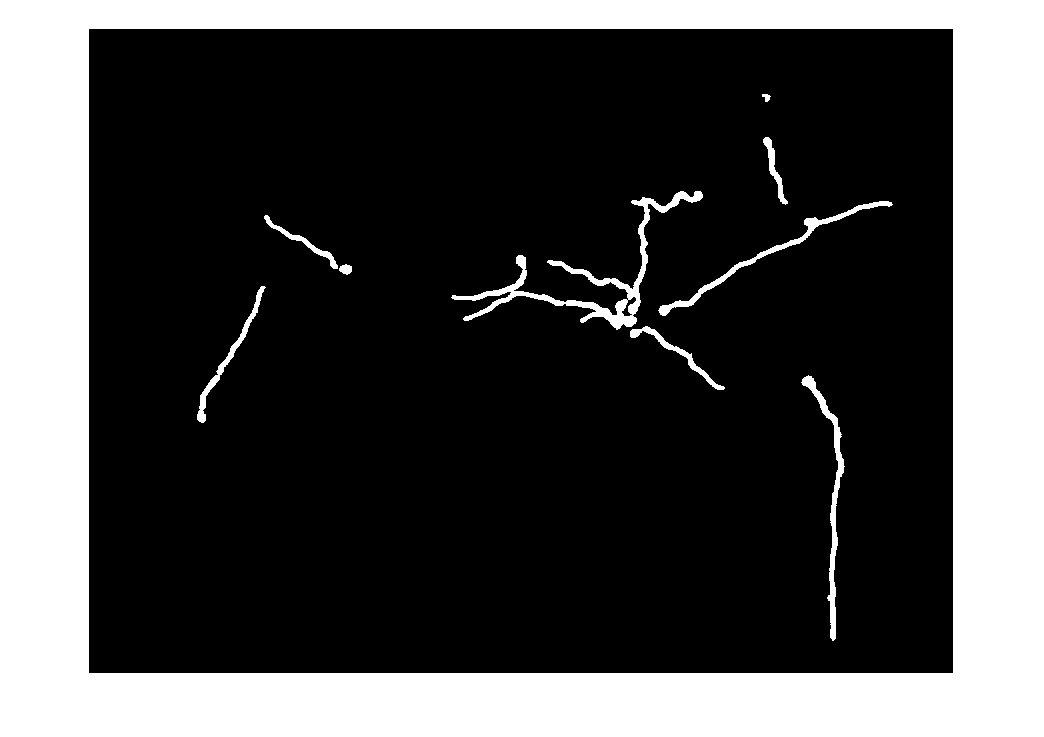

NumGerminatedSpores = 14

AverageLength = 354.3190

ratio = 0.0498

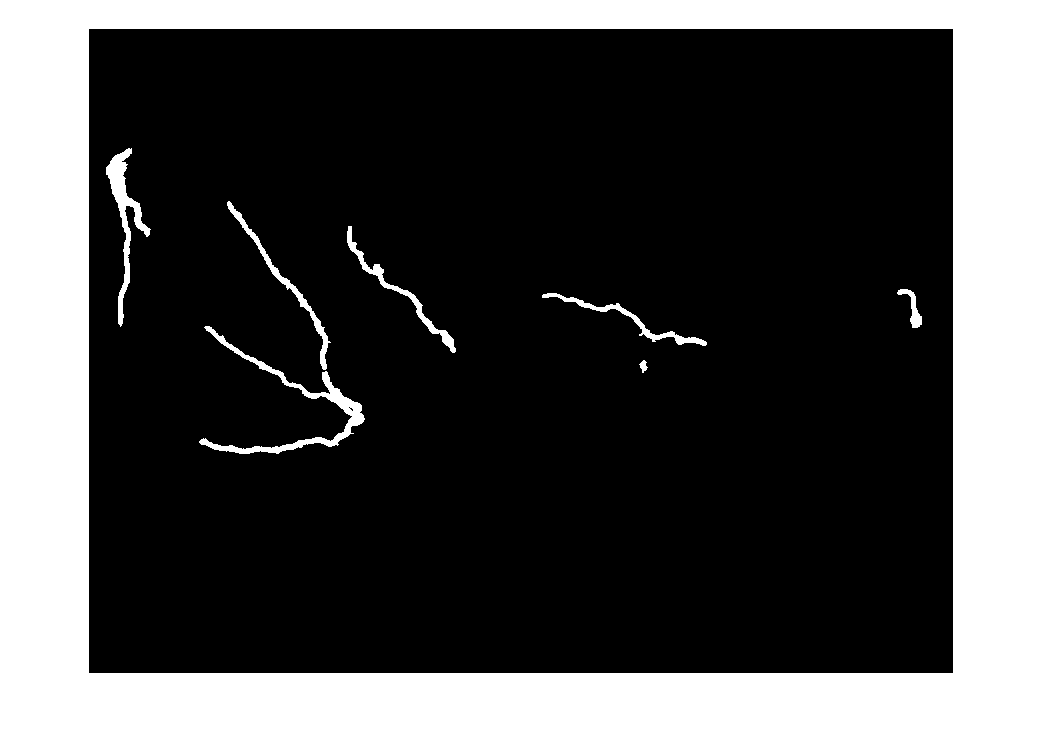

NumGerminatedSpores = 14

AverageLength = 289.3476

ratio = 2.0564

NumDetectedSpores = 53

ratio = 0.0514

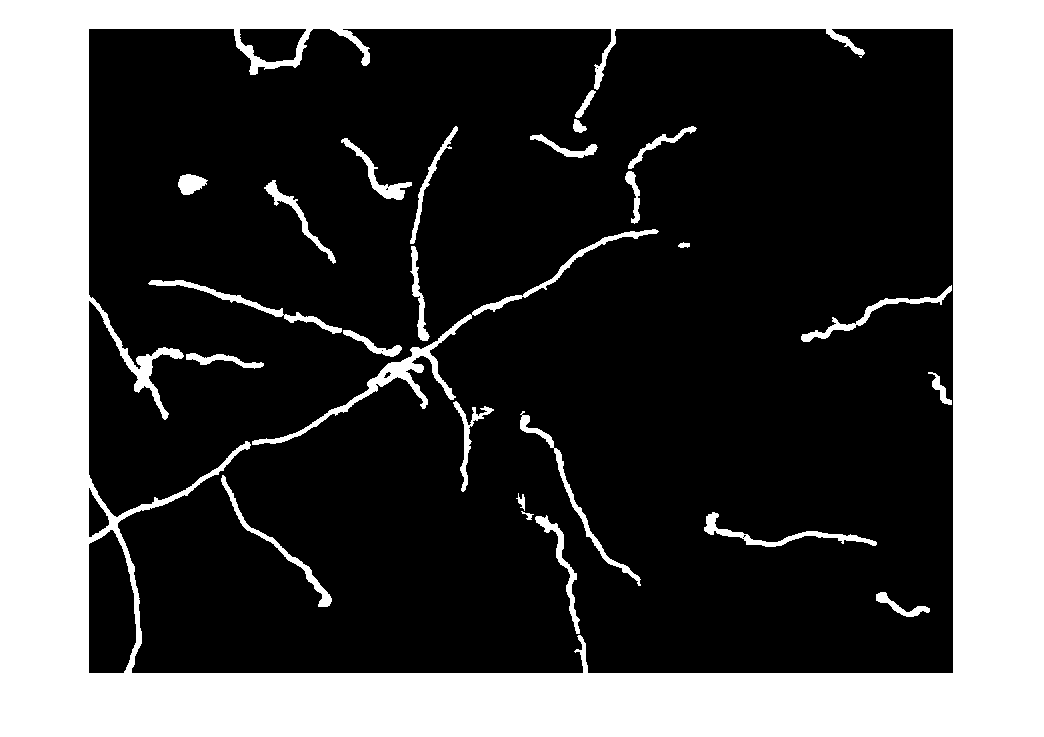

NumGerminatedSpores = 33

AverageLength = 364.2364

ratio = 0.0792

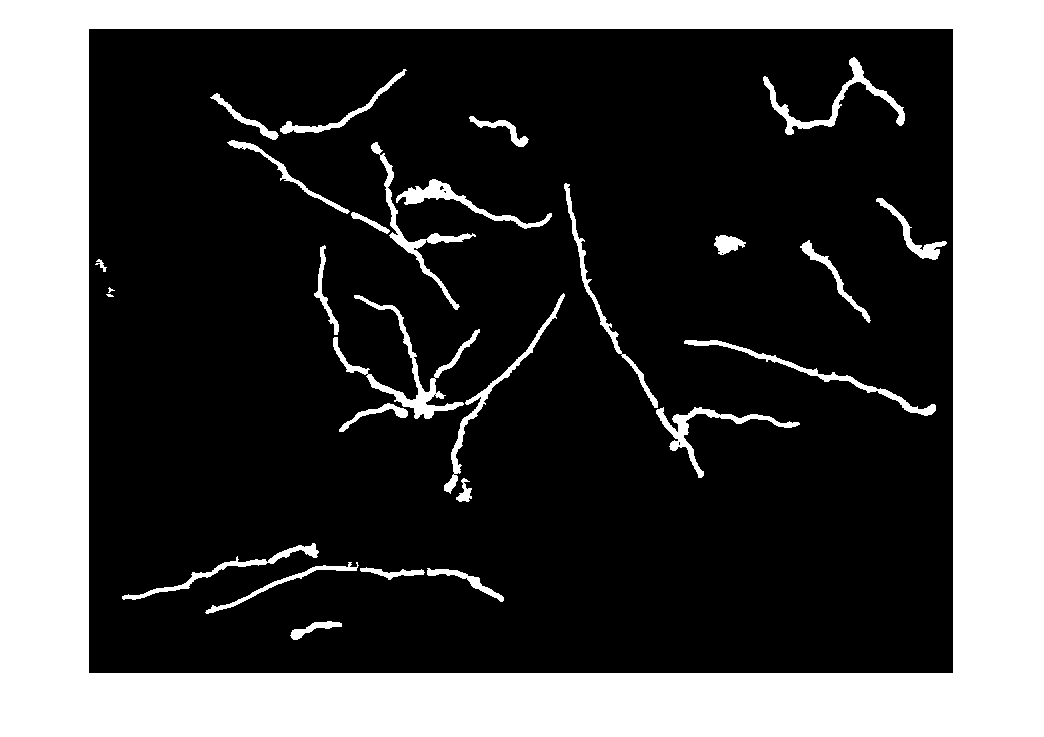

NumGerminatedSpores = 35

AverageLength = 321.4819

ratio = 0.0435

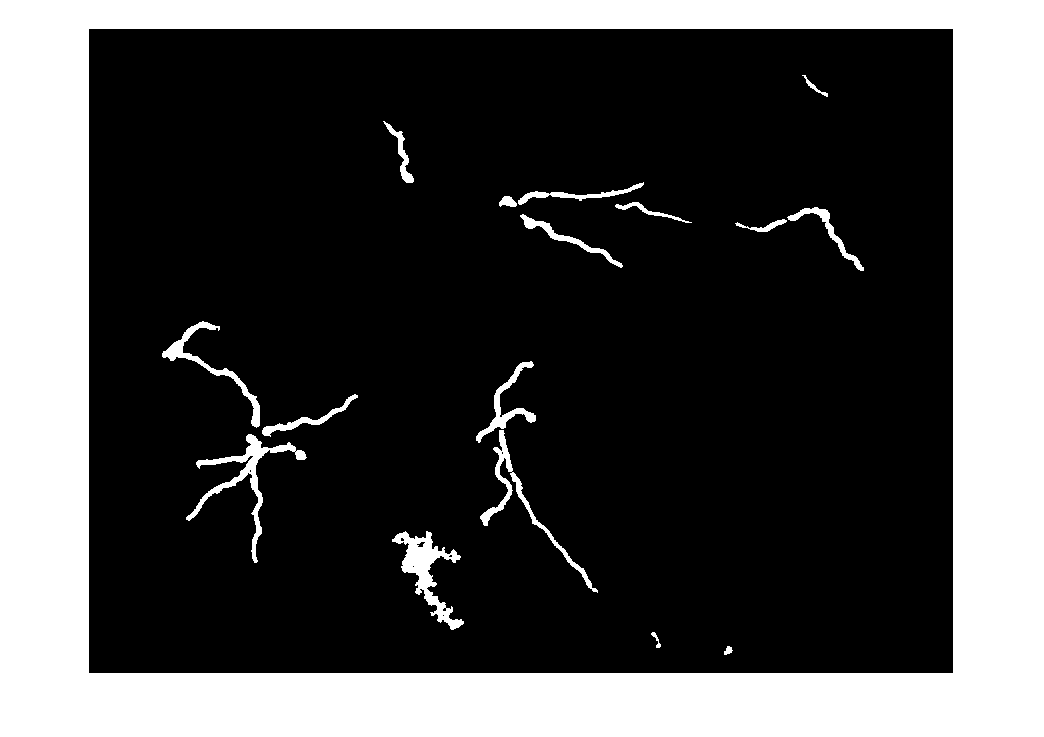

NumGerminatedSpores = 18

AverageLength = 343.9852

ratio = 0.0613

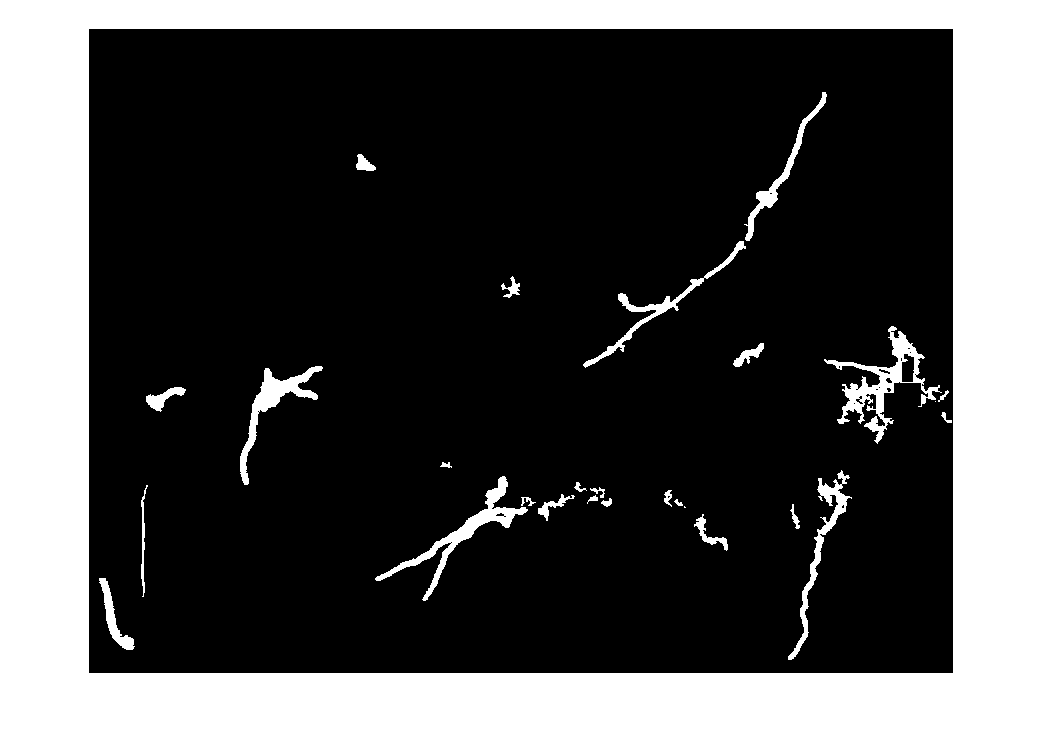

NumGerminatedSpores = 28

AverageLength = 269.6190

ratio = 0.0444

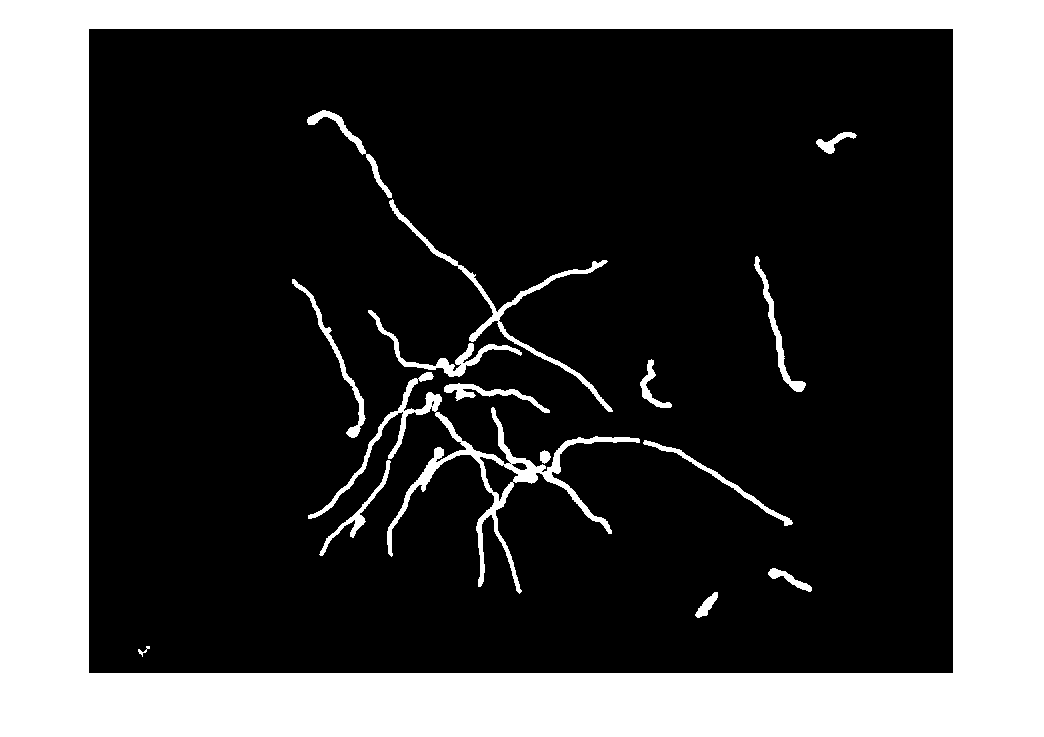

NumGerminatedSpores = 24

AverageLength = 363.1500

ratio = 0.0582

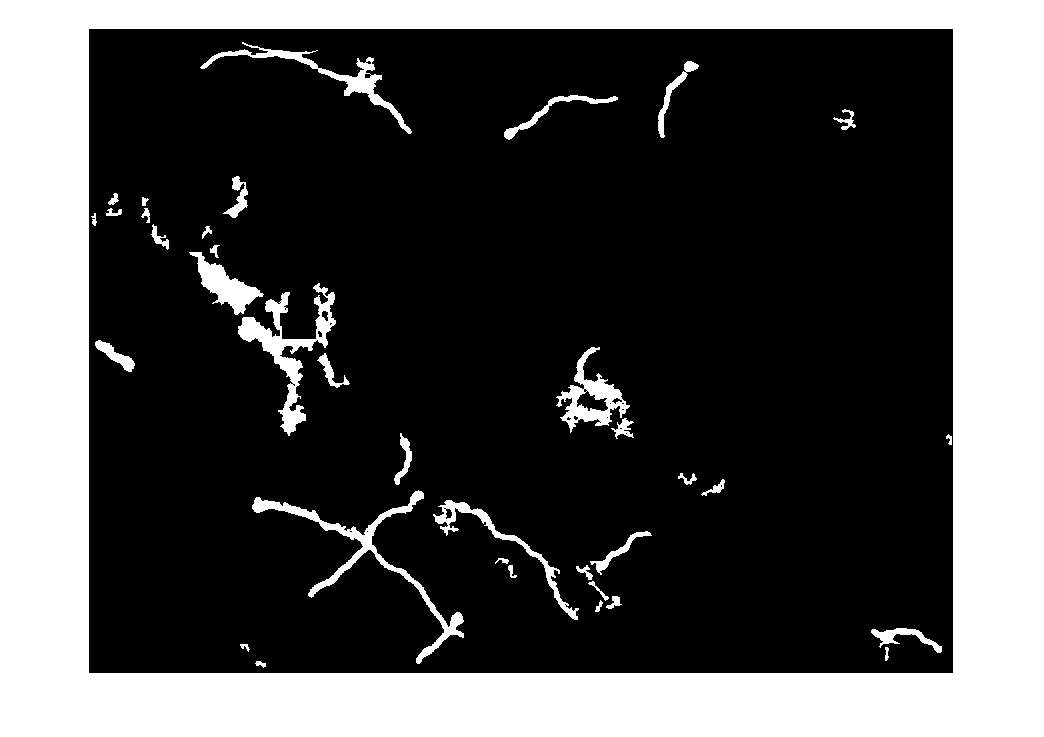

NumGerminatedSpores = 32

AverageLength = 321.1208

varType={'string','single','single','string'};
varName={'FileName','numGerminatedSpores','averageLength','Comments'};%,'AreaSpores'
T=table('Size',[0 4],'VariableTypes',varType,'VariableName',varName);

for i=1:numel(Images.Files)
    [I,info]=readimage(Images,i);
    labI=rgb2lab(I);
    ab=labI(:,:,1:2);
    ab=im2single(ab);
    nColors=2;
    pixel_labels=imsegkmeans(ab,nColors,'NumAttempts',3);
    Bin=imbinarize(pixel_labels);
    Bin1=imbinarize(pixel_labels);
    Im=rgb2gray(I);
    [count,pixels]=imhist(Bin);
    black=count(1);
    white=count(2);
    ratio=white/black
    SporesCenters=[];               
    SporesRadii=[];  
    
    if ratio>10
        Bin=imcomplement(Bin);
        Bin1=imcomplement(Bin);
        [count,pixels]=imhist(Bin);
        black=count(1);
        white=count(2);
        ratio=white/black
    end
    
    if ratio<0.1
        %check if there are germinative tube
        %delete touching-edge germinative tubes, but keep everithing if
        %removing the germinative tubes that touch the edges implies
        %removing too much
        
        %different way to extract binary image: works better to remove edge-touching spores
        %(if piecewise germinative tubes, with this method they are touching so
        %they belong so same connected component->removed all together. Using
        %first approach only one part of the tube might be deleted.)
        Im=mat2gray(Im);
        Im=imadjust(Im);
        filtImage = stdfilt(Im, ones(25));
        filtImage=imcomplement(filtImage);
        filteredImage=imbinarize(filtImage,'adaptive','Sensitivity',0.7);
        Bin_1=imcomplement(filteredImage);
                
        ConnComp_1=bwconncomp(Bin_1,4);
        N_1=ConnComp_1.NumObjects;
        stat_1=regionprops(ConnComp_1,'all');
%         figure;
%         imshow(Bin_1);
%         figure;
%         imshow(Bin_1);
        
        for j=1:N_1            
            x=stat_1(j).PixelList(:,1);
            y=stat_1(j).PixelList(:,2);
            if stat_1(j).Area<=2000            %find the isolated (non germinated) spores
                Bin(y,x)=0;                    %delete them from binary image --> only germinated spores left
                Bin1(y,x)=0;
                %I(y,x,3)=0;
            end 
            if  stat_1(j).Extent>=0.7     
                Bin(y,x)=0; 
                Bin1(y,x)=0;
                %I(y,x,2)=256;
            end
        end
        
        Threshold=(30*white)/100;                
        Cleaned=imclearborder(Bin_1,8);
        Edges=Bin_1-Cleaned;    
        Edges=imfill(Edges,'holes');
        Mask=logical(Edges);
        Bin(Mask)=0;
        Bin=imclearborder(Bin,8);
        [CountP1,Pixel1]=imhist(Bin);
        White1=CountP1(2);
        if White1<Threshold                    %if removed too much than keep everything
            Bin=Bin1;
%         else
%             I(Mask)=256;
        end
        ConnComp=bwconncomp(Bin,4);
        N=ConnComp.NumObjects;        
        stat=regionprops(ConnComp,'all');  
       
        for j=1:N                            %for each detected connected component
            if  stat(j).Area<=300            %find the isolated (non germinated) spores (leftovers from previous equivalent operation)
                x=stat(j).PixelList(:,1);    
                y=stat(j).PixelList(:,2);
                Bin(y,x)=0;                  %remove leftovers
                %I(y,x,3)=0;
            end
        end
        
        figure;
        imshow(Bin);
        [Centers,Radii]=imfindcircles(Bin,[11 20],'Sensitivity',0.9);     %look for circles(spores) in binary image in which non germinated spores have been removed  
        [columns rows]=meshgrid(1:size(Bin,2),1:size(Bin,1));        
        for k=1:numel(Radii)
            x=floor(Centers(k,1));          
            y=floor(Centers(k,2));
            array2D = (rows- y).^2+ (columns - x).^2<(Radii(k)-5)^2;
            if Bin(array2D)==1                       %if the circle contains only white pixels it means that it is really a spore
                %viscircles([x y],Radii(k));
                SporesCenters=[SporesCenters;[x y]]; %save location of detected spore
                SporesRadii(end+1)=Radii(k); 
                array2D = (rows- y).^2+ (columns - x).^2<(Radii(k))^2;
                Bin(array2D)=0;                      %hide pixels corresponding to spores (makes easier to compute length of tubes)
            end
        end 
        %repeat circles detection with different radius range: find more
        %circles in this way (don't know why). Keep only one copy of any double
        [Centers1,Radii1]=imfindcircles(Bin,[11 25],'Sensitivity',0.9);
        for k=1:numel(Radii1)
            xx=floor(Centers1(k,1));
            yy=floor(Centers1(k,2)); 
            array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k)-5)^2;
            if  isempty(SporesCenters)==0 & numel(find(SporesCenters==[xx yy]))==0 & Bin(array2D)==1
                %viscircles([xx yy],Radii1(k));
                SporesCenters=[SporesCenters;[xx yy]];
                SporesRadii(end+1)=Radii1(k);               
                array2D = (rows- yy).^2+ (columns - xx).^2<(Radii1(k))^2;
                Bin(array2D)=0;
            end
        end

        NumGerminatedSpores=numel(SporesRadii)  %how many germinated spores have been detected
        [CountPixels,PixelValue]=imhist(Bin);
        AreaGerminativeTubes=CountPixels(2);                 
        AverageTubeWidth=15;
        TotalLength=AreaGerminativeTubes/AverageTubeWidth;
        AverageLength=TotalLength/NumGerminatedSpores
        if White1<Threshold
            T(end+1,:)={sprintf('%s',info.Filename(23:end-4)),NumGerminatedSpores,AverageLength,sprintf('Edge-touching tubes not removed')};
        else
            T(end+1,:)={sprintf('%s',info.Filename(23:end-4)),NumGerminatedSpores,AverageLength,sprintf('')};
        end
        
    else
        [Centers,Radii]=imfindcircles(Im,[6 16],'Sensitivity',0.8,'EdgeThreshold',0.1,'ObjectPolarity','dark');
        %figure;
        %imshow(I);
        %viscircles(Centers,Radii);
        NumDetectedSpores=numel(Radii)
        T(end+1,:)={sprintf('%s',info.Filename(22:end-4)),NumDetectedSpores,0,sprintf('No germinated spores')};
   end
end

T

T = 10×4 table
          FileName           numGerminatedSpores    averageLength                Comments             
    _____________________    ___________________    _____________    _________________________________

    "\X100\T1\T1 1 X100"             19                794.02        "Edge-touching tubes not removed"
    "\X100\T1\T1 10 X100"            14                354.32        ""                               
    "\X100\T1\T1 2 X100"             14                289.35        ""                               
    "s\X100\T1\T1 3 X100"            53                     0        "No germinated spores"           
    "\X100\T1\T1 4 X100"             33                364.24        "Edge-touching tubes not removed"
    "\X100\T1\T1 5 X100"             35                321.48        ""                               
    "\X100\T1\T1 6 X100"